# Draw ACC1.eps

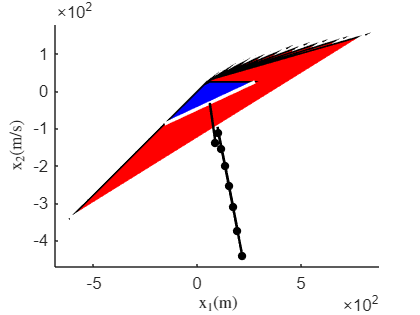

    figure;
    font_size=10;
    two_column_width=7;
    set(gcf, 'Units', 'inches', 'Position', [1, 1, two_column_width/2, two_column_width/2*0.75]);
    if length(XSet)>1
        for i=1:floor(length(XSet)/10):length(XSet), plot(XSet(i));hold on;end
    else
        plot(XSet);hold on
    end 
    plot(Xf,'color','blue');hold on
    
    ylabel('$\mathrm{x_2(m/s)}$', 'Interpreter', 'latex', 'FontSize', font_size); % Y-axis label with FontSize
    xlabel('$\mathrm{x_1(m)}$', 'Interpreter', 'latex', 'FontSize', font_size); % X-axis label with FontSize
    set(gca, 'FontSize',font_size);
    set(findall(gca, 'Type', 'text'), 'FontSize',font_size);
    set(findall(gcf, '-property', 'FontSize'), 'FontSize', font_size);
    set(gcf, 'Units', 'inches', 'Position', [1, 1, two_column_width/2, two_column_width/2*0.75]);
    ax = gca;
    ax.YAxis.Exponent = 2;
    ax.XAxis.Exponent = 2; 
    grid off;
    
    exportgraphics(gcf, 'Figures\ACC1.eps','ContentType','vector');